load datatable.mat
data = table2array(datatable)

data = 	1.0e+03 *

    0.0010    0.1000    0.3000    0.0020    0.0986    0.8272
    0.0010    0.1000    0.3000    0.0035    0.0986    1.4836
    0.0010    0.1000    0.3000    0.0050    0.0986    1.8205
    0.0010    0.1000    0.4000    0.0020    0.1424    0.7886
    0.0010    0.1000    0.4000    0.0035    0.1422    1.4178
    0.0010    0.1000    0.4000    0.0050    0.1422    1.7922
    0.0010    0.1000    0.5000    0.0020    0.1008    0.8405
    0.0010    0.1000    0.5000    0.0035    0.1008    1.3499
    0.0010    0.1000    0.5000    0.0050    0.1008    2.0871
    0.0010    0.1200    0.3000    0.0020    0.1180    0.7961



p = data(:,1:4)';
t = data(:,5:6)';

p1 = p(1,:);
p2 = p(2,:);
p3 = p(3,:);
p4 = p(4,:);

t1 = t(1,:);
t2 = t(2,:);

Polynomial equation with interactions terms

quadraticfun1 = @(b,p)( ...
    +b(1).*p1 ...  
    +b(2).*p2 ...
    +b(3).*p3 ...
    +b(4).*p4 ...
    +b(5).*p1.*p1 ...
    +b(6).*p2.*p2 ...
    +b(7).*p3.*p3 ...
    +b(8).*p4.*p4 ...
    +b(9).*p1.*p2 ...
    +b(10).*p1.*p3 ...
    +b(11).*p1.*p4 ...
    +b(12).*p2.*p3 ...
    +b(13).*p2.*p4 ...
    +b(14).*p3.*p4 ...
    +b(15) ...
    );


p must be a matrix. if multiple variable are included, do not use multiple vectors but a matrix.

beta0 = ones(15,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


b = nlinfit(p,t1,quadraticfun1,beta0)

b =   -87.5346
    1.6142
   -0.1330
    0.1005
   18.7871
   -0.0031
   -0.0000
   -0.0143
   -0.2938
    0.0142


Polynomial equation with interactions terms

quadraticfun2 = @(c,p)( ...
    +c(1).*p1 ...  
    +c(2).*p2 ...
    +c(3).*p3 ...
    +c(4).*p4 ...
    +c(5).*p1.*p1 ...
    +c(6).*p2.*p2 ...
    +c(7).*p3.*p3 ...
    +c(8).*p4.*p4 ...
    +c(9).*p1.*p2 ...
    +c(10).*p1.*p3 ...
    +c(11).*p1.*p4 ...
    +c(12).*p2.*p3 ...
    +c(13).*p2.*p4 ...
    +c(14).*p3.*p4 ...
    +c(15) ...
    );


p must be a matrix. if multiple variable are included, do not use multiple vectors but a matrix.

beta0 = ones(15,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


c = nlinfit(p,t2,quadraticfun2,beta0)

c = 	1.0e+03 *

    0.4596
    0.0212
   -0.0017
    1.8543
    0.0454
   -0.0000
    0.0000
   -0.1881
   -0.0022
    0.0000


cubicfun1 = @(d,p)( ...
    +d(1).*p1 ...  
    +d(2).*p2 ...
    +d(3).*p3 ...
    +d(4).*p4 ...
    +d(5).*p1.*p1 ...
    +d(6).*p2.*p2 ...
    +d(7).*p3.*p3 ...
    +d(8).*p4.*p4 ...
    +d(9).*p1.*p2 ...
    +d(10).*p1.*p3 ...
    +d(11).*p1.*p4 ...
    +d(12).*p2.*p3 ...
    +d(13).*p2.*p4 ...
    +d(14).*p3.*p4 ...
    +d(15).*p1.*p1.*p1 ...
    +d(16).*p1.*p1.*p2 ...
    +d(17).*p1.*p2.*p2 ...
    +d(18).*p2.*p2.*p2 ...
    +d(19));
    

p must be a matrix. if multiple variable are included, do not use multiple vectors but a matrix.

beta0 = ones(19,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


d = nlinfit(p,t1,cubicfun1,beta0)

d =   -58.9508
   18.9000
   -0.1245
    0.0881
    1.3488
   -0.1398
   -0.0000
   -0.0125
   -0.3091
    0.0195


cubicfun2 = @(e,p)( ...
    +e(1).*p1 ...  
    +e(2).*p2 ...
    +e(3).*p3 ...
    +e(4).*p4 ...
    +e(5).*p1.*p1 ...
    +e(6).*p2.*p2 ...
    +e(7).*p3.*p3 ...
    +e(8).*p4.*p4 ...
    +e(9).*p1.*p2 ...
    +e(10).*p1.*p3 ...
    +e(11).*p1.*p4 ...
    +e(12).*p2.*p3 ...
    +e(13).*p2.*p4 ...
    +e(14).*p3.*p4 ...
    +e(15).*p1.*p1.*p1 ...
    +e(16).*p1.*p1.*p2 ...
    +e(17).*p1.*p2.*p2 ...
    +e(18).*p2.*p2.*p2 ...
    +e(19));
    

p must be a matrix. if multiple variable are included, do not use multiple vectors but a matrix.

beta0 = ones(19,1) %%% initial coefficient value %%%%

beta0 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


e = nlinfit(p,t2,cubicfun2,beta0)

e = 	1.0e+03 *

   -0.7668
    0.0823
   -0.0017
    1.9453
    0.5493
   -0.0006
    0.0000
   -0.1998
    0.0036
    0.0001


%[j,k]=meshgrid(1:0.02:2,120:0.8:160)
[u,v]=meshgrid(300:4:500,2:0.06:5)

u =    300   304   308   312   316   320   324   328   332   336   340   344   348   352   356   360   364   368   372   376   380   384   388   392   396   400   404   408   412   416   420   424   428   432   436   440   444   448   452   456   460   464   468   472   476   480   484   488   492   496
   300   304   308   312   316   320   324   328   332   336   340   344   348   352   356   360   364   368   372   376   380   384   388   392   396   400   404   408   412   416   420   424   428   432   436   440   444   448   452   456   460   464   468   472   476   480   484   488   492   496
   300   304   308   312   316   320   324   328   332   336   340   344   348   352   356   360   364   368   372   376   380   384   388   392   396   400   404   408   412   416   420   424   428   432   436   440   444   448   452   456   460   464   468   472   476   480   484   488   492   496
   300   304   308   312   316   320   324   328   332   336   340   344   348   352   356   

v =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2.0600    2

j = 1.5.*ones(51);
k = 140.*ones(51);
%u = 400.*ones(51);
%v = 3.5.*ones(51);
x1 = p1;
x2 = p2;
x3 = p3;
x4 = p4;

cubicresp1 = ( ...
    +d(1).*x1 ...  
    +d(2).*x2 ...
    +d(3).*x3 ...
    +d(4).*x4 ...
    +d(5).*x1.*x1 ...
    +d(6).*x2.*x2 ...
    +d(7).*x3.*x3 ...
    +d(8).*x4.*x4 ...
    +d(9).*x1.*x2 ...
    +d(10).*x1.*x3 ...
    +d(11).*x1.*x4 ...
    +d(12).*x2.*x3 ...
    +d(13).*x2.*x4 ...
    +d(14).*x3.*x4 ...
    +d(15).*x1.*x1.*x1 ...
    +d(16).*x1.*x1.*x2 ...
    +d(17).*x1.*x2.*x2 ...
    +d(18).*x2.*x2.*x2 ...
    +d(19));

cubicresp2 = ( ...
    +e(1).*x1 ...  
    +e(2).*x2 ...
    +e(3).*x3 ...
    +e(4).*x4 ...
    +e(5).*x1.*x1 ...
    +e(6).*x2.*x2 ...
    +e(7).*x3.*x3 ...
    +e(8).*x4.*x4 ...
    +e(9).*x1.*x2 ...
    +e(10).*x1.*x3 ...
    +e(11).*x1.*x4 ...
    +e(12).*x2.*x3 ...
    +e(13).*x2.*x4 ...
    +e(14).*x3.*x4 ...
    +e(15).*x1.*x1.*x1 ...
    +e(16).*x1.*x1.*x2 ...
    +e(17).*x1.*x2.*x2 ...
    +e(18).*x2.*x2.*x2 ...
    +e(19));

responsesurf1 = ( ...
    +b(1).*x1 ...  
    +b(2).*x2 ...
    +b(3).*x3 ...
    +b(4).*x4 ...
    +b(5).*x1.*x1 ...
    +b(6).*x2.*x2 ...
    +b(7).*x3.*x3 ...
    +b(8).*x4.*x4 ...
    +b(9).*x1.*x2 ...
    +b(10).*x1.*x3 ...
    +b(11).*x1.*x4 ...
    +b(12).*x2.*x3 ...
    +b(13).*x2.*x4 ...
    +b(14).*x3.*x4 ...
    +b(15) ...
    );

responsesurf2 = ( ...
    +c(1).*x1 ...  
    +c(2).*x2 ...
    +c(3).*x3 ...
    +c(4).*x4 ...
    +c(5).*x1.*x1 ...
    +c(6).*x2.*x2 ...
    +c(7).*x3.*x3 ...
    +c(8).*x4.*x4 ...
    +c(9).*x1.*x2 ...
    +c(10).*x1.*x3 ...
    +c(11).*x1.*x4 ...
    +c(12).*x2.*x3 ...
    +c(13).*x2.*x4 ...
    +c(14).*x3.*x4 ...
    +c(15) ...
    );

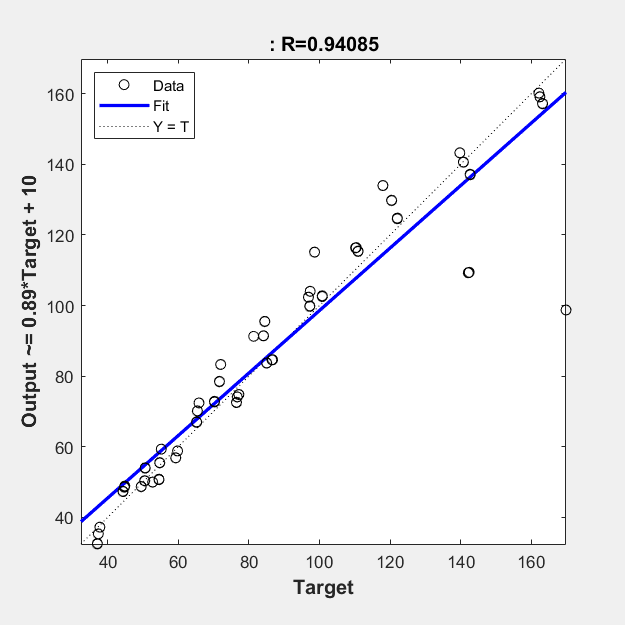

% plotregression(t1,cubicresp1);
% hold off;
plotregression(t1,cubicresp1);
hold off;

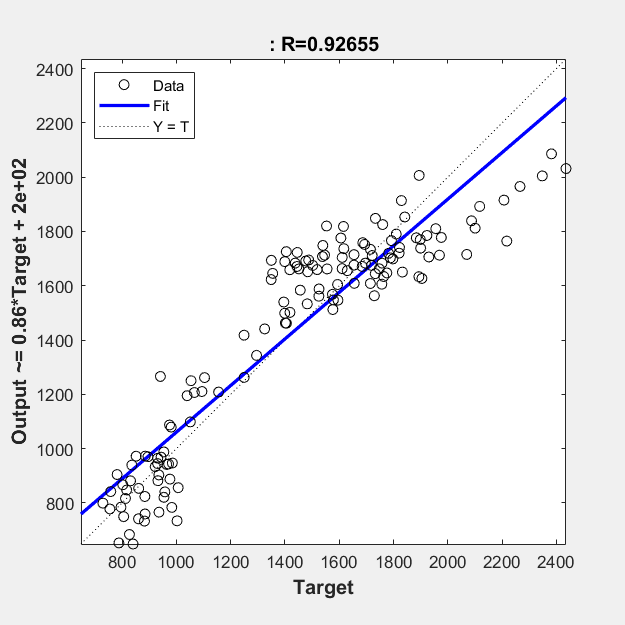

plotregression(t2,cubicresp2);

%[w,x]=meshgrid(0:0.02:1,0:0.02:1)
[y,z]=meshgrid(0:0.02:1,0:0.02:1)

y =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800
         0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0

z =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0

w = 0.5.*ones(51);
x = 0.5.*ones(51);
%y = 0.5.*ones(51);
%z = 0.5.*ones(51);
for row=1:51
    for column=1:51
        predinput=[w(row,column);x(row,column);y(row,column);z(row,column)]
        pred = poslin(predinput);
        ipfpred(row,column) = pred(1,1);
        seapred(row,column) = pred(2,1);
    end
end

predinput =     0.5000
    0.5000
         0
         0


predinput =     0.5000
    0.5000
    0.0200
         0


predinput =     0.5000
    0.5000
    0.0400
         0


predinput =     0.5000
    0.5000
    0.0600
         0


predinput =     0.5000
    0.5000
    0.0800
         0


predinput =     0.5000
    0.5000
    0.1000
         0


predinput =     0.5000
    0.5000
    0.1200
         0


predinput =     0.5000
    0.5000
    0.1400
         0


predinput =     0.5000
    0.5000
    0.1600
         0


predinput =     0.5000
    0.5000
    0.1800
         0


predinput =     0.5000
    0.5000
    0.2000
         0


predinput =     0.5000
    0.5000
    0.2200
         0


predinput =     0.5000
    0.5000
    0.2400
         0


predinput =     0.5000
    0.5000
    0.2600
         0


predinput =     0.5000
    0.5000
    0.2800
         0


predinput =     0.5000
    0.5000
    0.3000
         0


predinput =     0.5000
    0.5000
    0.3200
         0


predinput =     0.5000
    0.5000
    0.3400
         0


predinput =     0.5000
    0.5000
    0.3600
         0


predinput =     0.5000
    0.5000
    0.3800
         0


predinput =     0.5000
    0.5000
    0.4000
         0


predinput =     0.5000
    0.5000
    0.4200
         0


predinput =     0.5000
    0.5000
    0.4400
         0


predinput =     0.5000
    0.5000
    0.4600
         0


predinput =     0.5000
    0.5000
    0.4800
         0


predinput =     0.5000
    0.5000
    0.5000
         0


predinput =     0.5000
    0.5000
    0.5200
         0


predinput =     0.5000
    0.5000
    0.5400
         0


predinput =     0.5000
    0.5000
    0.5600
         0


predinput =     0.5000
    0.5000
    0.5800
         0


predinput =     0.5000
    0.5000
    0.6000
         0


predinput =     0.5000
    0.5000
    0.6200
         0


predinput =     0.5000
    0.5000
    0.6400
         0


predinput =     0.5000
    0.5000
    0.6600
         0


predinput =     0.5000
    0.5000
    0.6800
         0


predinput =     0.5000
    0.5000
    0.7000
         0


predinput =     0.5000
    0.5000
    0.7200
         0


predinput =     0.5000
    0.5000
    0.7400
         0


predinput =     0.5000
    0.5000
    0.7600
         0


predinput =     0.5000
    0.5000
    0.7800
         0


predinput =     0.5000
    0.5000
    0.8000
         0


predinput =     0.5000
    0.5000
    0.8200
         0


predinput =     0.5000
    0.5000
    0.8400
         0


predinput =     0.5000
    0.5000
    0.8600
         0


predinput =     0.5000
    0.5000
    0.8800
         0


predinput =     0.5000
    0.5000
    0.9000
         0


predinput =     0.5000
    0.5000
    0.9200
         0


predinput =     0.5000
    0.5000
    0.9400
         0


predinput = 4×1
    0.5000
    0.5000
    0.9600
         0


predinput = 4×1
    0.5000
    0.5000
    0.9800
         0


predinput = 4×1
    0.5000
    0.5000
    1.0000
         0


predinput = 4×1
    0.5000
    0.5000
         0
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.0200


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.0200


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.0200


predinput = 4×1
    0.5000
    0.5000
         0
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.0400


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.0400


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.0400


predinput = 4×1
    0.5000
    0.5000
         0
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.0600


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.0600


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.0600


predinput = 4×1
    0.5000
    0.5000
         0
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.0800


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.0800


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.0800


predinput = 4×1
    0.5000
    0.5000
         0
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.1000


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.1000


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.1000


predinput = 4×1
    0.5000
    0.5000
         0
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.1200


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.1200


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.1200


predinput = 4×1
    0.5000
    0.5000
         0
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.1400


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.1400


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.1400


predinput = 4×1
    0.5000
    0.5000
         0
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.1600


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.1600


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.1600


predinput = 4×1
    0.5000
    0.5000
         0
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.1800


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.1800


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.1800


predinput = 4×1
    0.5000
    0.5000
         0
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.2000


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.2000


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.2000


predinput = 4×1
    0.5000
    0.5000
         0
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.2200


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.2200


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.2200


predinput = 4×1
    0.5000
    0.5000
         0
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.2400


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.2400


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.2400


predinput = 4×1
    0.5000
    0.5000
         0
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.2600


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.2600


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.2600


predinput = 4×1
    0.5000
    0.5000
         0
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.2800


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.2800


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.2800


predinput = 4×1
    0.5000
    0.5000
         0
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.3000


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.3000


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.3000


predinput = 4×1
    0.5000
    0.5000
         0
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.3200


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.3200


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.3200


predinput = 4×1
    0.5000
    0.5000
         0
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.3400


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.3400


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.3400


predinput = 4×1
    0.5000
    0.5000
         0
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.3600


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.3600


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.3600


predinput = 4×1
    0.5000
    0.5000
         0
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.3800


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.3800


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.3800


predinput = 4×1
    0.5000
    0.5000
         0
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.4000


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.4000


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.4000


predinput = 4×1
    0.5000
    0.5000
         0
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.4200


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.4200


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.4200


predinput = 4×1
    0.5000
    0.5000
         0
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.4400


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.4400


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.4400


predinput = 4×1
    0.5000
    0.5000
         0
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.4600


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.4600


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.4600


predinput = 4×1
    0.5000
    0.5000
         0
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.4800


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.4800


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.4800


predinput = 4×1
    0.5000
    0.5000
         0
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.5000


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.5000


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.5000


predinput = 4×1
    0.5000
    0.5000
         0
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.5200


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.5200


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.5200


predinput = 4×1
    0.5000
    0.5000
         0
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.5400


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.5400


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.5400


predinput = 4×1
    0.5000
    0.5000
         0
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.5600


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.5600


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.5600


predinput = 4×1
    0.5000
    0.5000
         0
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.5800


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.5800


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.5800


predinput = 4×1
    0.5000
    0.5000
         0
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.6000


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.6000


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.6000


predinput = 4×1
    0.5000
    0.5000
         0
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.6200


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.6200


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.6200


predinput = 4×1
    0.5000
    0.5000
         0
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.6400


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.6400


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.6400


predinput = 4×1
    0.5000
    0.5000
         0
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.6600


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.6600


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.6600


predinput = 4×1
    0.5000
    0.5000
         0
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.6800


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.6800


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.6800


predinput = 4×1
    0.5000
    0.5000
         0
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.7000


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.7000


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.7000


predinput = 4×1
    0.5000
    0.5000
         0
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.7200


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.7200


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.7200


predinput = 4×1
    0.5000
    0.5000
         0
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.9000
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.9200
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.9400
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.9600
    0.7400


predinput = 4×1
    0.5000
    0.5000
    0.9800
    0.7400


predinput = 4×1
    0.5000
    0.5000
    1.0000
    0.7400


predinput = 4×1
    0.5000
    0.5000
         0
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.0200
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.0400
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.0600
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.0800
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.1000
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.1200
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.1400
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.1600
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.1800
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.2000
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.2200
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.2400
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.2600
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.2800
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.3000
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.3200
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.3400
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.3600
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.3800
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.4000
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.4200
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.4400
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.4600
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.4800
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.5000
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.5200
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.5400
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.5600
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.5800
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.6000
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.6200
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.6400
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.6600
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.6800
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.7000
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.7200
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.7400
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.7600
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.7800
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.8000
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.8200
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.8400
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.8600
    0.7600


predinput = 4×1
    0.5000
    0.5000
    0.8800
    0.7600


ANNIPF = ((ipfpred)*(max(data(:,5))-min(data(:,5))))+min(data(:,5))
ANNSEA = ((seapred)*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

%[j,k]=meshgrid(1:0.02:2,120:0.8:160)
[u,v]=meshgrid(300:4:500,2:0.06:5)
mesh(j,k,responsesurf1,'FaceAlpha',0.5,'EdgeColor','#FFFFFF','FaceColor','r');
grid on;
box on;
ax = gca;
ax.GridLineStyle = ':';
ax.GridAlpha = 0.4;
ax.TickDir = 'in';
set(gca, 'FontName', 'Times New Roman','FontSize',14,'FontSmoothing', ...
    'on','LineWidth',1.5,'TickLength',[0.025 0.025])
xlabel('\ittr');
ylabel('\itA1\rm (mm)')
zlabel('IPF (kN)')
view(60,45)
hold on;
mesh(j,k,ANNIPF,'FaceAlpha',0.5,'EdgeColor','#FFFFFF','FaceColor','#0072BD');
plot3(p1,p2,t1,'k.','MarkerSize',15);
hold off;
zlim([0 200])
legend('RSM','ANN-ReLu','');
legend('Position',[0.050065,0.85425,0.23062,0.1046])

mesh(u,v,responsesurf2./1000,'FaceAlpha',0.5,'EdgeColor','#FFFFFF','FaceColor','r');
grid on;
box on;
ax = gca;
ax.GridLineStyle = ':';
ax.GridAlpha = 0.4;
ax.TickDir = 'in';
set(gca, 'FontName', 'Times New Roman','FontSize',14,'FontSmoothing', ...
    'on','LineWidth',1.5,'TickLength',[0.025 0.025])
xlabel('\itL\rm (mm)');
ylabel('\itT\rm (mm)')
zlabel('SEA (kJ/kg)')
view(60,45)
hold on;
mesh(u,v,ANNSEA./1000,'FaceAlpha',0.5,'EdgeColor','#FFFFFF','FaceColor','#0072BD');
plot3(p3(1,37:45),p4(1,37:45),t2(1,37:45)./1000,'k.','MarkerSize',15);
hold off;
zlim([0 2.5])
legend('RSM','ANN-ReLu','');
legend('Position',[0.050065,0.85425,0.23062,0.1046])
